%This should allow you to chack and "fix" data if the solver has failed
%prematurely or something like that resulting in a very bad asymptotic
%velocity. To start with, load the b, i and v profiles into the workspace
%in matlab that you want to work with.

t=0:0.1:50;
dx=0.1; %Change this if appropriate (what you ran the solver with)

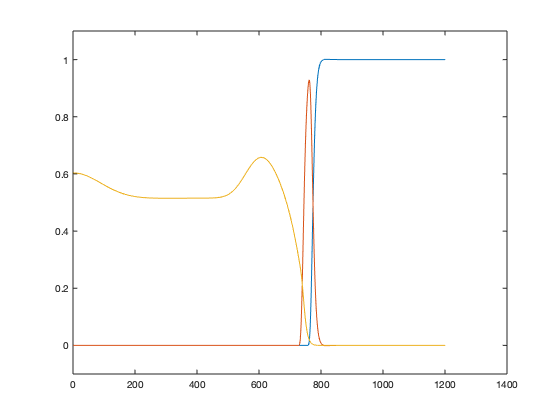

%Plots the profiles at the max time reached. The issue will likely be
%obvious (large bulge in v curve or something like that).
minus=0;
plot(b(end-minus, :))
hold on
plot(i(end-minus, :))
plot(v(end-minus, :))
hold off
ylim([-0.1 1.1])

%This section tracks the velocity from the available data in the same way
%as the original code.

%pre-assign vectors for velocity and front positions
p=zeros(1,size(b, 1)-minus);
midB=zeros(1,size(b, 1)-minus);
midI=zeros(1,size(b, 1)-minus);
frontB=zeros(1,size(b, 1)-minus);

%find all of the relavent front positions and work out velcoity and
%widths
t0=1;
for j=1:size(b, 1)-minus
    midB(j)=find(b(j,:)>0.5,1);
    if(midB(j)>10 && t0==1) 
        t0=j;
    end
    if(j>t0+2)
        a=polyfit(t(t0:j),midB(t0:j),1);
        p(j)=a(1);
        midI(j)=find((i(j,:)+b(j,:))>0.5,1);
        frontB(j)=find(b(j,:)>0.99,1);
    end
end
velocity=zeros(length(p));
widthB=zeros(length(p));
widthI=zeros(length(p));
velocity=p*dx;
avv=mean(velocity(end-20:end)); 
widthB=(frontB-midB)*dx*2;
avw_B=mean(widthB(end-20:end));
widthI=(midB-midI)*dx;
avw_I=mean(widthI(end-20:end));   

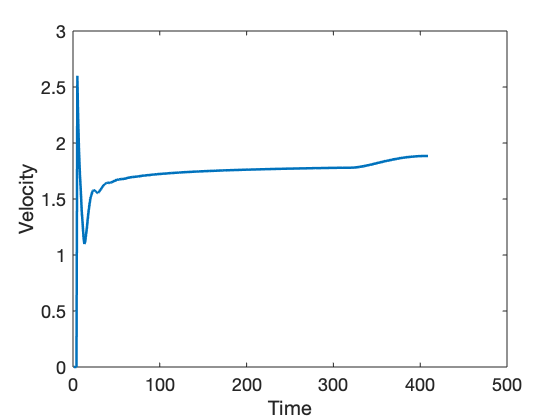

%Plot velocity as function of time (again, time where issue occurs should
%be fairly clear
plot(velocity, 'LineWidth', 2.5)
ylabel('Velocity')
xlabel('Time')
% ylim([1.8-0.5 1.8+0.25])
% xlim([0 510])
set(gca, 'FontSize', 18)

% plot(midB*dx, velocity, 'LineWidth', 2.5)
% ylabel('Velocity')
% xlabel('Front Position')
% % ylim([1.8-0.5 1.8+0.25])
% % xlim([0 510])
% set(gca, 'FontSize', 18)

% Define the range for the 'good' velocity data. By default this usually
% runs 200:end, but will likely need to change "stop" to be something
% earlier (before the error occurs). Try to avoid moving the start too
% early (poor asymptote fit).
stop=500;
startT=200;

%Finds new asymptotic velocity value
avv=mean(velocity(stop-20:stop)); 
avw_B=mean(widthB(stop-20:stop));
avw_I=mean(widthI(stop-20:stop)); 
midB_dat=midB(startT:stop);
t_dat=t(startT:stop);
v_dat=velocity(startT:stop);
fun_x = @(x)asymptotefcn(x,midB_dat,v_dat);
x0=avv+0.01;
v_asymptote_x = fminsearch(fun_x,x0);
if v_asymptote_x>2*avv
    v_asymptote_x=avv;
end
fun_t = @(x)asymptotefcn(x,t_dat,v_dat);
v_asymptote_t = fminsearch(fun_t,x0);
if v_asymptote_t>2*avv
    v_asymptote_t=avv;
end

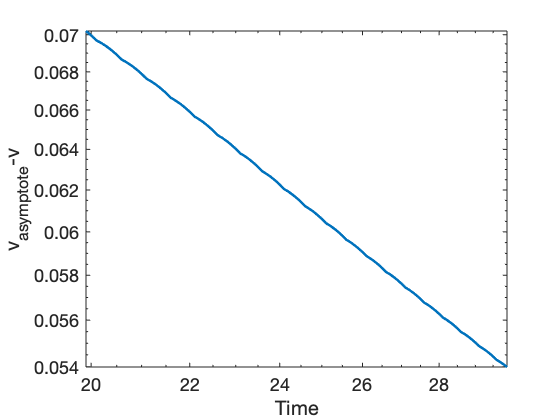

%This should be a straight line. Change "stop" and "startT" above so that
%it looks straight.
loglog(t_dat, v_asymptote-v_dat, 'LineWidth', 2.5)
xlabel('Time')
ylabel('v_{asymptote}-v')
set(gca, 'FontSize', 18)

%Save results
% K=4.0*0.95;
% save('Jones_Burst_Y80_L40_dx01_A10_fix.mat','avv', 'avw_B', 'avw_I', 'b', 'i', 'v', 'K', 'v_asymptote');

% y_dat_x=v_asymptote_x-v_dat;
% fit_x = polyfit(log(midB_dat),log(y_dat_x), 1);
% m_x = fit_x(1);
% k_x = fit_x(2);
% midB_test=linspace(40, 200);
% y_fit_x = (midB_test*10).^m_x.*exp(k_x);
% loglog(midB_dat*dx, v_asymptote_x-v_dat, 'LineWidth', 2.5)
% hold on
% loglog(midB_test, y_fit_x, 'LineWidth', 2.5)
% hold off
% xlabel('Front Position')
% ylabel('v_{asymptote}-v')
% set(gca, 'FontSize', 18)

% plot(midB*dx, velocity, 'LineWidth', 2.5)
% hold on
% plot(midB_test, v_asymptote_x-y_fit_x, 'k--', 'LineWidth', 2.5)
% hold off
% ylabel('Velocity')
% xlabel('Front Position')
% % ylim([1.8-0.5 1.8+0.25])
% % xlim([0 510])
% set(gca, 'FontSize', 18)

% y_dat_t=v_asymptote_t-v_dat;
% fit_t = polyfit(log(t_dat),log(y_dat_t), 1);
% m_t = fit_t(1);
% k_t = fit_t(2);
% t_test=linspace(20, 100);
% y_fit_t = (t_test).^m_t.*exp(k_t);
% loglog(t_dat, v_asymptote_t-v_dat, 'LineWidth', 2.5)
% hold on
% loglog(t_test, y_fit_t, 'LineWidth', 2.5)
% hold off
% xlabel('Front Position')
% ylabel('v_{asymptote}-v')
% set(gca, 'FontSize', 18)

% plot(t, velocity, 'LineWidth', 2.5)
% hold on
% plot(t_test, v_asymptote_t-y_fit_t, 'k--', 'LineWidth', 2.5)
% hold off
% ylabel('Velocity')
% xlabel('Front Position')
% % ylim([1.8-0.5 1.8+0.25])
% % xlim([0 510])
% set(gca, 'FontSize', 18)

function f = asymptotefcn(x, t_data, v_data)
    y_data=x-v_data;
    fit = polyfit(log(t_data),log(y_data), 1);
    m = fit(1);
    k = fit(2);
    y_fit = t_data.^m.*exp(k);
    f=sum((y_fit-y_data).^2);
    if ~isreal(f)
        f=10;
    end
end